f=@(x) (x-1).^2+(x.^2-3).^2 %minimize (derivative)

f = function_handle with value:
    @(x)(x-1).^2+(x.^2-3).^2


df=derivate(f)

df = function_handle with value:
    @(x)x.*2.0+x.*(x.^2-3.0).*4.0-2.0


ddf=derivate(df) %second derivative for Newton method

ddf = function_handle with value:
    @(x)x.^2.*1.2e+1-1.0e+1



x=1

x =      1



%Newton method
format long
for i=1:10
    x=x-df(x)/ddf(x);
end
x

x =    1.672981647854942


y=x^2

y =    2.798867594059438


dist=sqrt(f(x))

dist =    0.702394862644220


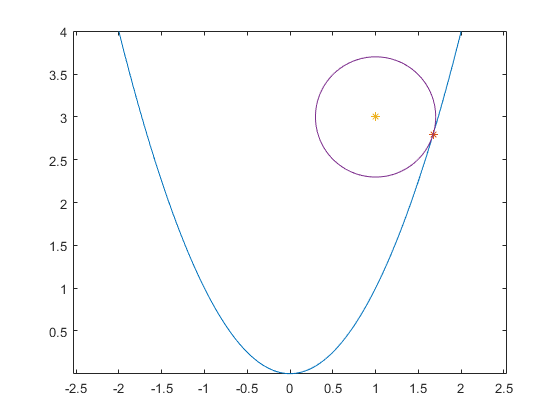

xx=linspace(-2,2,1000);
plot(xx,xx.^2)
axis equal
hold on
plot(x,y,'*')
hold on
plot(1,3,'*')
hold on
circle(1,3,dist)
hold off

[x,num] = newton_method(df,1,0.001)

x =    1.672981647861896


num =      8


[x,num] = secant_method(df,1,2,0.001)

x =    1.672972934839602


num =      5


[x,num] = regula_falsi_method(df,1,2,0.001)

x =    1.672813569589584


num =      6


function circle(x,y,r)
%x and y are the coordinates of the center of the circle
%r is the radius of the circle
%0.01 is the angle step, bigger values will draw the circle faster but
%you might notice imperfections (not very smooth)
ang=0:0.01:2*pi; 
xp=r*cos(ang);
yp=r*sin(ang);
plot(x+xp,y+yp);
end

function [x,num] = newton_method(f,x0,error)
%Newton method

df=derivate(f);
x=x0;x_prev=Inf;
num=0;
format long
while abs(x-x_prev)>error
    x_prev=x;
    x=x-f(x)/df(x);
    num=num+1; 
end
end

function [x2,num] = secant_method(f,x0,x1,error)
%Secant method

f0=f(x0);f1=f(x1);
num=0;
format long
while abs(x0-x1)>error
    x2=x1-f1*(x1-x0)/(f1-f0); 
    f2=f(x2);
    x0=x1;x1=x2;f0=f1;f1=f2;
    num=num+1; 
end
end

function [x2,num] = regula_falsi_method(f,x0,x1,error)
%Regula-falsi method

root_found=false;
f0=f(x0);f1=f(x1);
x2=x1-f1*(x1-x0)/(f1-f0);
f2=f(x2);
num=1;
format long
while abs(x2-x1)>error && not(root_found)
    if (f2*f0<0) 
        x1=x2;f1=f2;
    elseif (f2*f1<0)
        x0=x1;x1=x2;f0=f1;f1=f2;
    else
        root_found=true;
    end
    x2=x1-f1*(x1-x0)/(f1-f0);
    f2=f(x2);
    num=num+1; 
end
end